U = 5

U = 5

I = 1.5e-3

I = 0.0015


%Device coefficients PT100
a = 3.9083e-3

a = 0.0039

b = -5.775e-7

b = -5.7750e-07

c = -4.183e-12

c = -4.1830e-12


R0 = 100 %Ohm at 25°C

R0 = 100

T = linspace (0,50,5)

T =          0   12.5000   25.0000   37.5000   50.0000



%PT100 Formula with coefficient b
R1 = R0*(1+a.*T+b.*T.^2)

R1 =   100.0000  104.8764  109.7347  114.5749  119.3971



%PT100 Formula without coefficient b
R2 = R0*(1+a.*T)

R2 =   100.0000  104.8854  109.7708  114.6561  119.5415


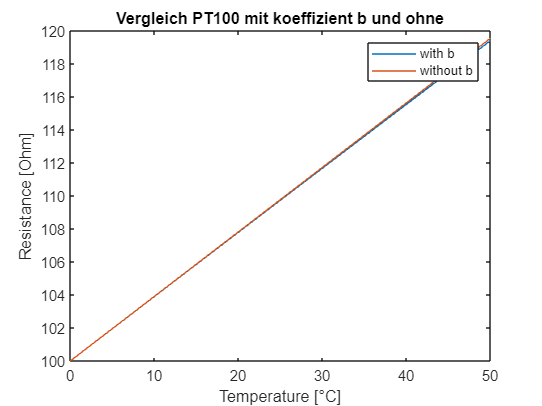



plot(T,R1,T,R2)
title("Vergleich PT100 mit koeffizient b und ohne");
xlabel('Temperature [°C]');
ylabel('Resistance [Ohm]');
legend('with b', 'without b');


Rtmin = R0*(1+a*0)

Rtmin = 100

Rtmax = R0*(1+a*50)

Rtmax = 119.5415


Rv = U/I - Rtmin

Rv = 3.2333e+03